data = load("resultadosCSV_lvds.txt");
length(data)

ans =         1024



stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start =     27


n_max_start = 335

n_max_start =    335


T           = 5e-9;

% tau = mean([tau_stop, tau_start])
tau = tau_stop

tau =      1.572000000000000e-11



T_buscado = 1/(2*2.5e6)

T_buscado =      2.000000000000000e-07


T_buscado/T

ans =     40


tiempo_muerto = 15*5e-9

tiempo_muerto =      7.500000000000000e-08


% t_fino = (start)*tau_start - (stop)*tau_stop;
t_fino = (start-stop)*tau

t_fino = 	1.0e+-8 *

   0.009433962264151
   0.012578616352201
   0.012578616352201
   0.012578616352201
   0.009433962264151
   0.012578616352201
   0.012578616352201
   0.009433962264151
   0.009433962264151
   0.012578616352201


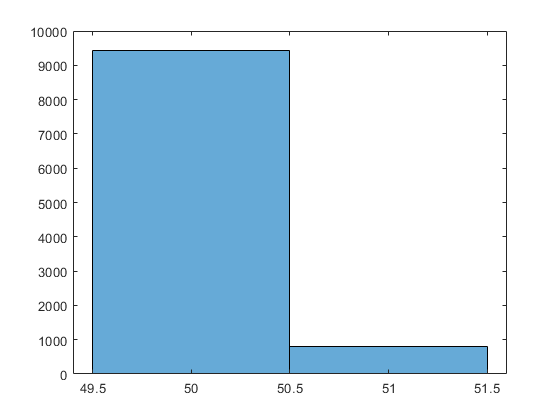

t = (coarse*T) + t_fino;

histogram(coarse)

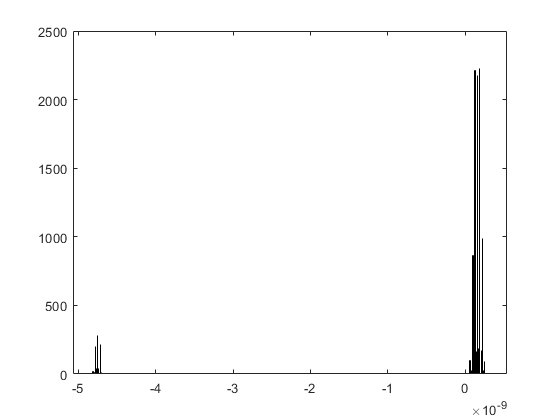

histogram(t_fino, 1024)

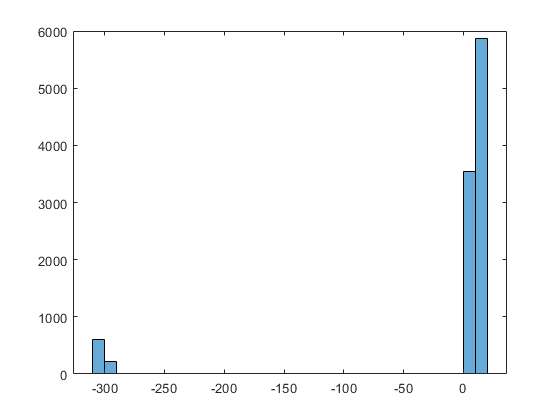

histogram((start-stop))

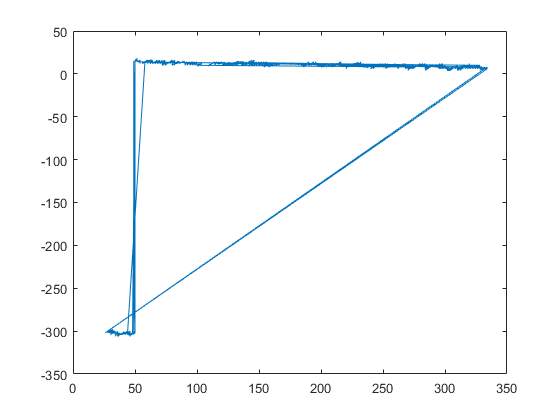

plot(start, start-stop)


st = start-stop

st =      6
     8
     8
     8
     6
     8
     8
     6
     6
     8


indices_st = find(st>0)

indices_st =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


st_positivo = st(indices_st);
std(st_positivo)

ans =    2.508116657575284


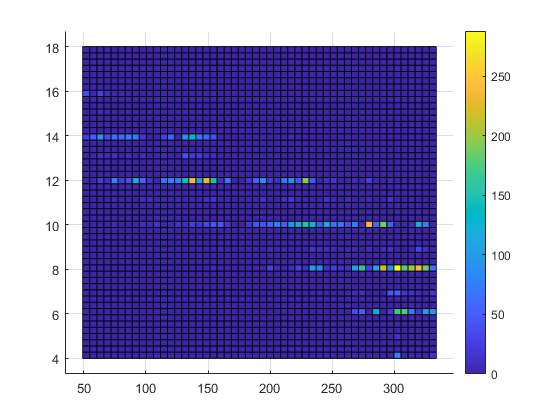

hist3([start(indices_st), st_positivo], 'CdataMode','auto', 'Nbins',[50 50])
view(2)
colorbar

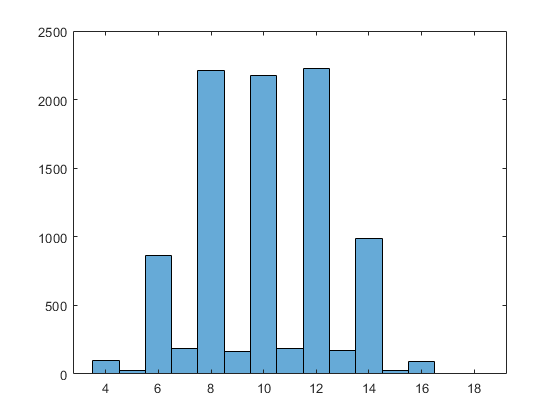

histogram(st(st>0))



x = 1:1024

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


plot(x, start, x, stop)

Error using plot
Vectors must be the same length.



% bines = -0.5:1:400.5
% histogram(start, bines)

st = start-stop;
indices_st = find(st>0);
indices_st_neg = find(st<0);
st(indices_st_neg) = st(indices_st_neg) + (n_max_start-n_min_start);
st_positivo = st(indices_st);
std(st_positivo)

ans =    1.621934206070240


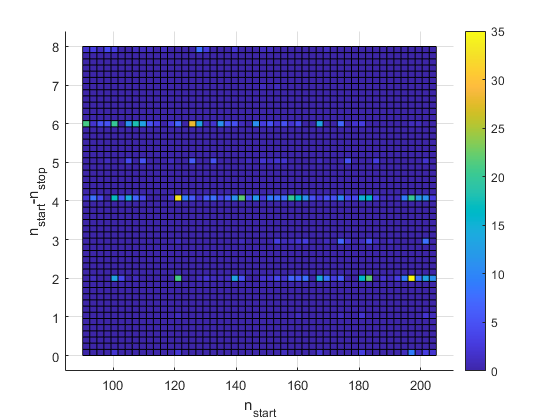

hist3([start, st], 'CdataMode','auto', 'Nbins',[50 50])
view(2); colorbar; ylabel('n_{start}-n_{stop}'); xlabel('n_{start}')
exportgraphics(gcf,'start-stop_lvds.eps');